# 电池产热和温度

clear;
clc;
tic
I=-17.5*[ones(2000,1);zeros(300,1);-ones(2000,1);zeros(3700,1)];

dVdTLMO=importdata("dVdTLMO.txt");
dVdTC=importdata('dVdTC.txt');
load Rohm_matrix.mat;
indexT=(0:5:50)+298.15-25;
Rohm=[indexT',Rohm_matrix(1,:)'];
T=298.15;
Tamb=298.15;

## 电池基本参数

Lpos=183e-6;
Lsep=52e-6;
Lneg=100e-6;
Lsum=Lpos+Lsep+Lneg;

Rsp=8e-6;
Rsn=12.5e-6;

epsspos=0.297;
epssneg=0.471;

F=96485.33289;
Aera=1;

cs0pos=3900;
cs0neg=14870;

csmaxpos=22860;
csmaxneg=26390;

Qp=Lpos*epsspos*Aera*csmaxpos*F/3600;
Qn=Lneg*epssneg*Aera*csmaxneg*F/3600;

soc0pos=cs0pos/csmaxpos;
soc0neg=cs0neg/csmaxneg;

socp=soc0pos-cumsum(I/3600/Qp);
socn=soc0neg+cumsum(I/3600/Qn);

## 产热与电池温度

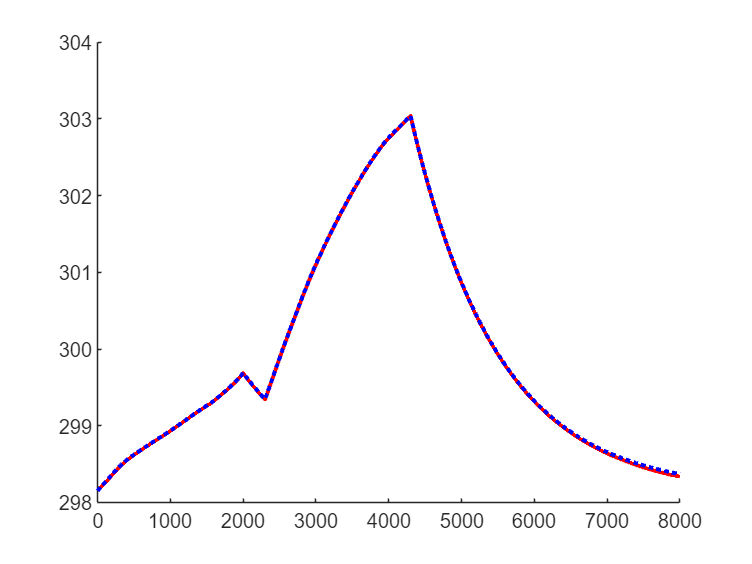

rho=2407.3;
Cp=1105.9;
h=2.2325e+3;
Tl(1)=298.15;
entro=[];
for i=1:8000
    Entro=I(i)*Tl(i)*(interp1(dVdTLMO(:,1),dVdTLMO(:,2),socp(i),'linear','extrap')...
        -interp1(dVdTC(:,1),dVdTC(:,2),socn(i),'linear',"extrap"));
    Qh(i)=I(i)^2*interp1(Rohm(:,1),Rohm(:,2),Tl(i),'linear','extrap')+Entro;
    dTdt=(h*(Tamb-Tl(i))+Qh(i)/Lsum)/rho/Cp;
    Tl(i+1)=Tl(i)+dTdt;
    entro=[entro;Entro];
end
T_p2d=importdata("T_p2d.txt");

figure(1);
clf;
hold on;
plot(T_p2d(:,2),'LineWidth',2,"Color",'r');
plot(Tl(2:end),'LineWidth',2,'Color','b',"LineStyle",":");

max(T_p2d(:,2))-298.15

ans =        4.8847


max(Tl)-298.15

ans =        4.8851


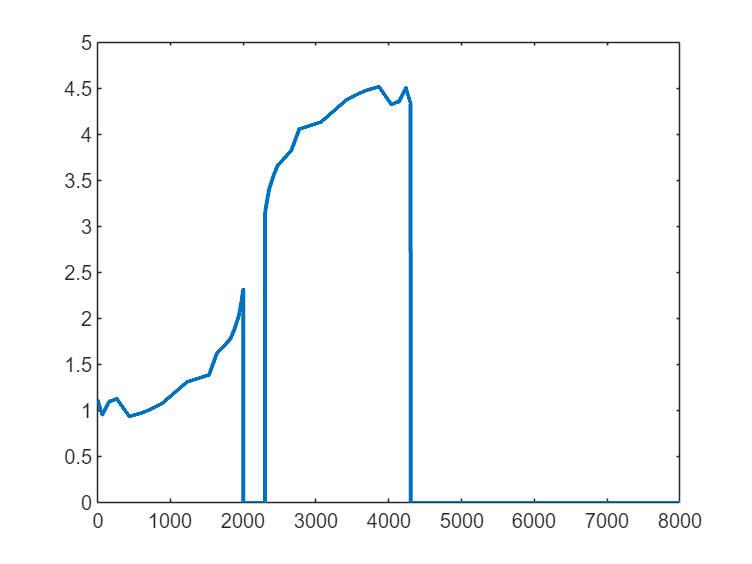

figure(2);
clf;
plot(Qh,'LineWidth',2);

## 表面锂浓差电热耦合

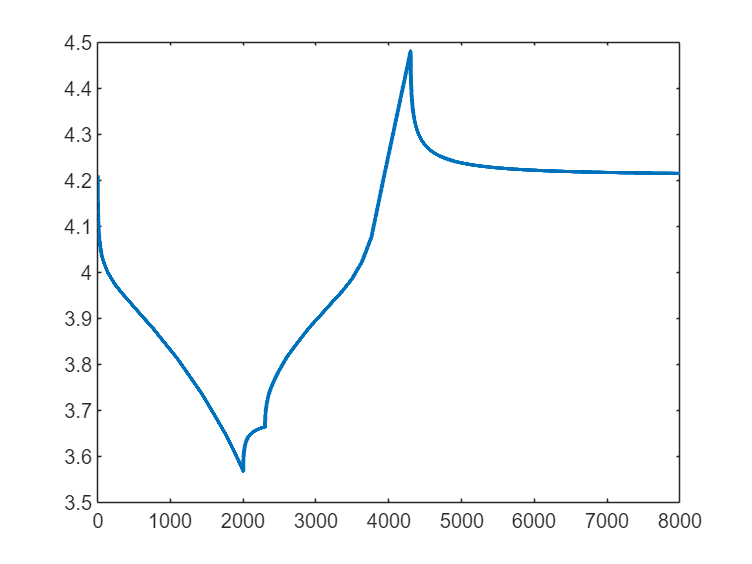

% dsocpl=[];
% dsocnl=[];
% for i=1:8000    
%     Dsn=1.4523e-13*exp(68025.7/8.314*(1/(318)-1/(Tl(i))));
%     Dsp=1e-14*exp(20000/8.314*(1/(298)-1/(Tl(i))));
%     [dsocp,dsocn]=fom(Rsp,Rsn,Dsp,Dsn,I,Qp,Qn);
%     dsocpl=[dsocpl,dsocp];
%     dsocnl=[dsocnl,dsocn];
% end
% load dsocnl.mat;
% load dsocpl.mat;

load diag_dsocn.mat;
load diag_dsocp.mat;
diag_dsocp=diag(dsocpl);
diag_dsocn=diag(dsocnl);

Eeq_pos=importdata('Eeq_LMO.txt');
Eeq_neg=importdata('Eeq_neg.txt');

socpsurf=socp-diag_dsocp;
socnsurf=socn+diag_dsocn;

Ebatt=interp1(Eeq_pos(:,1),Eeq_pos(:,2),socpsurf,'linear','extrap')...
    -interp1(Eeq_neg(:,1),Eeq_neg(:,2),socnsurf,'linear','extrap');
figure(3);
clf;
plot(Ebatt,'LineWidth',2);

## 液相扩散电热耦合

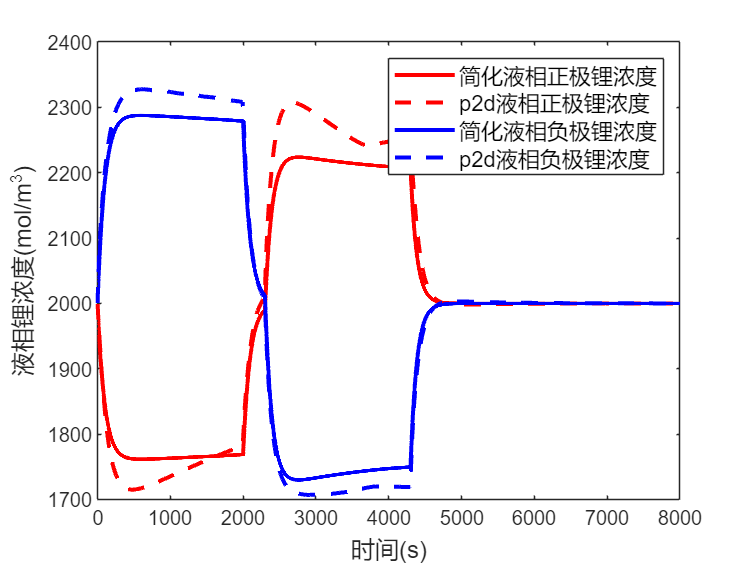

cl=2000;
epsl=0.4;
Xequ=(-2*Lneg^2+3*Lsep^2+2*Lpos^2+6*Lsep*Lpos)/6/Lsum;
P=-epsl*(Lneg^2/3+Lneg*Xequ+Xequ^2/2);
Q1=-2/(Lneg+2*Xequ);
Q2=-2/(Lpos+2*(Lsep-Xequ));
t_plus=0.363;
Rg=8.314;

dcen(1)=0;
dcep(1)=0;

for i=1:8000
    De=10^(-8.43-54/(Tl(i+1)-229-0.005*cl)-cl*2.2e-4);
    ddcen=De*epsl^1.5*dcen(i)/P-(1-t_plus)*I(i)/F/Aera/P/Q1;
    dcen(i+1)=dcen(i)+ddcen;
    ddcep=De*epsl^1.5*dcep(i)/P+(1-t_plus)*I(i)/F/Aera/P/Q2;
    dcep(i+1)=dcep(i)+ddcep;
end
cen=dcen(2:end)+2000;
cep=dcep(2:end)+2000;
V_ce=(1+t_plus)*2*Rg*T/F*log(cep./cen);
V_ce=V_ce';
p2d_cep=importdata('p2d_cep.txt');
p2d_cep=p2d_cep(:,2);
p2d_cen=importdata('p2d_cen.txt');
p2d_cen=p2d_cen(:,2);
V_ce_p2d=(1+t_plus)*2*Rg*T/F*log(p2d_cep./p2d_cen);

figure(2);
clf;
plot(cep(2:end),'LineWidth',2,"Color",'r');
hold on;
plot(p2d_cep,'LineWidth',2,"Color",'r','LineStyle',"--");
plot(cen(2:end),'LineWidth',2,"Color",'b');
plot(p2d_cen,'LineWidth',2,"Color",'b','LineStyle',"--");
legend('简化液相正极锂浓度','p2d液相正极锂浓度','简化液相负极锂浓度','p2d液相负极锂浓度',"FontSize",11);
xlabel('时间(s)',"FontSize",12);
ylabel('液相锂浓度(mol/m^3)',"FontSize",12);

## 电化学反应电热耦合

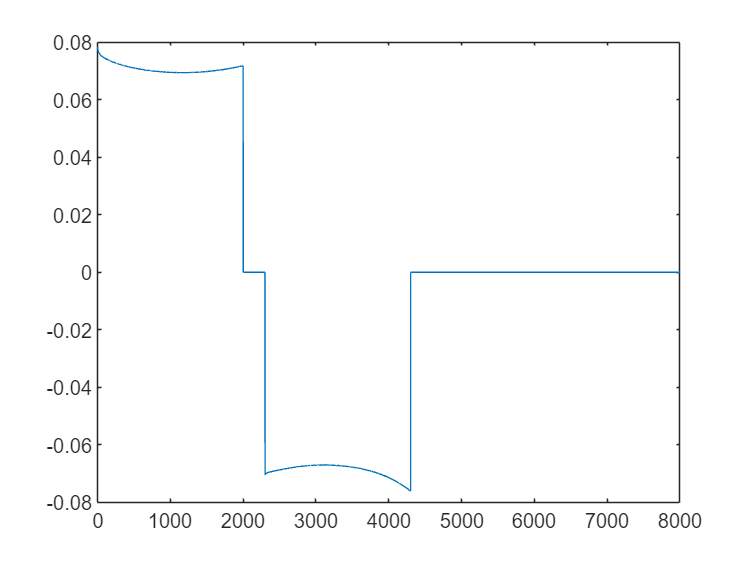

for i=1:8000
i0refn=17.71*exp(21350/Rg*(1/298.15-1/Tl(i+1)));
i0refp=-16.74*exp(20500/Rg*(1/298.15-1/Tl(i+1)));

i0n(i)=i0refn*(2*socnsurf(i))^0.5*(2*(1-socnsurf(i)))^0.5*(cen(i)/1000)^0.5;
i0p(i)=i0refp*(2*socpsurf(i))^0.5*(2*(1-socpsurf(i)))^0.5*(cep(i)/1000)^0.5;

icn(i)=I(i)/i0n(i);
icp(i)=I(i)/i0p(i);

V_ct(i)=2*Rg*T/F*log((icp(i)+sqrt(icp(i)^2+1))/((icn(i)+sqrt(icn(i)^2+1))));
end

figure(3);
clf;
plot(V_ct);

## 欧姆内阻电热耦合

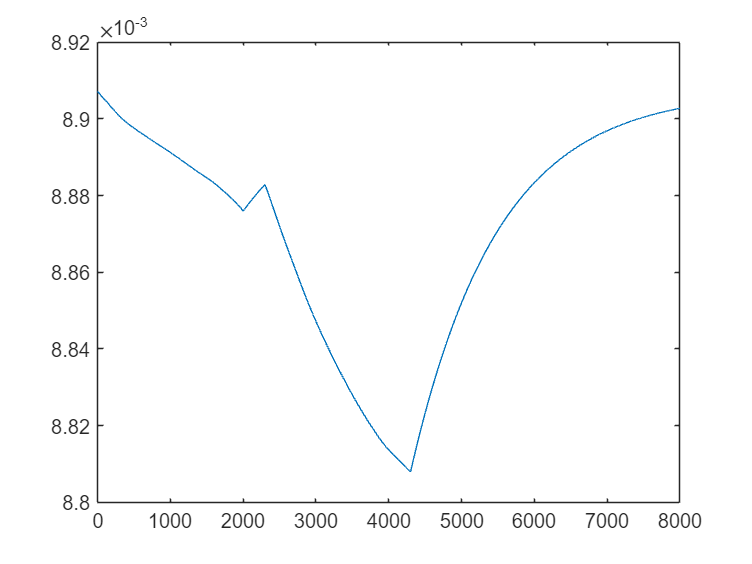

for i=1:8000
    R_ohm(i)=interp1(Rohm(:,1),Rohm(:,2),Tl(i+1));
end
figure(4);
clf;
plot(R_ohm);

U=Ebatt+V_ce+R_ohm'.*I;
toc

历时 6.008483 秒。


## 未电热耦合

tic
Dsnwt=1.4523e-13*exp(68025.7/8.314*(1/(318)-1/(298.15)));
Dspwt=1e-14*exp(20000/8.314*(1/(298)-1/(298.15)));
[dsocpwt,dsocnwt]=fom(Rsp,Rsn,Dspwt,Dsnwt,I,Qp,Qn);

socpsurfwt=socp-dsocpwt;
socnsurfwt=socn+dsocnwt;

Ewt=interp1(Eeq_pos(:,1),Eeq_pos(:,2),socpsurfwt,'linear','extrap')...
    -interp1(Eeq_neg(:,1),Eeq_neg(:,2),socnsurfwt,'linear','extrap');

Dewt=10^(-8.43-54/(298.15-229-0.005*cl)-cl*2.2e-4);

dcenwt(1)=0;
dcepwt(1)=0;

for i=1:8000
    ddcenwt=Dewt*epsl^1.5*dcenwt(i)/P-(1-t_plus)*I(i)/F/Aera/P/Q1;
    dcenwt(i+1)=dcenwt(i)+ddcenwt;
    ddcepwt=Dewt*epsl^1.5*dcepwt(i)/P+(1-t_plus)*I(i)/F/Aera/P/Q2;
    dcepwt(i+1)=dcepwt(i)+ddcepwt;
end
cenwt=dcenwt(2:end)+2000;
cepwt=dcepwt(2:end)+2000;
V_cewt=(1+t_plus)*2*Rg*T/F*log(cepwt./cenwt);
V_cewt=V_cewt';
Uwt=Ewt+R_ohm(1)*I;
toc

历时 0.380945 秒。


## 电池端电压

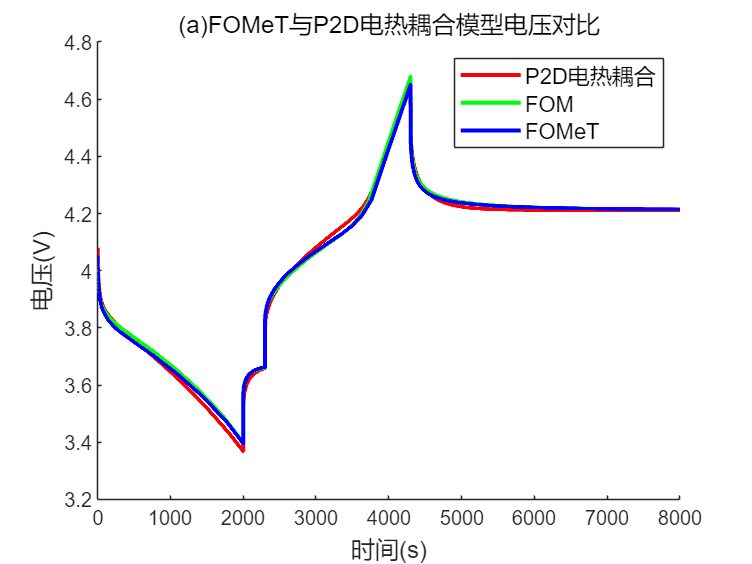


p2d_U=importdata('p2d_u.txt');
p2d_U=p2d_U(:,2);
figure(5);
clf;
hold on;
plot(p2d_U,'LineWidth',2,"Color",'r');
plot(Uwt,'LineWidth',2,"Color",'g');
plot(U,'LineWidth',2,"Color",'b');
xlabel('时间(s)',"FontSize",12);
ylabel('电压(V)',"FontSize",12);
title('(a)FOMeT与P2D电热耦合模型电压对比','FontSize',12);
legend('P2D电热耦合','FOM','FOMeT',"FontSize",11);

RMSE=sqrt(mean((U-p2d_U).^2)) %matrix2=0.0161,matrix=0.0144

RMSE =      0.014352


RMSE=sqrt(mean((Uwt-p2d_U).^2))

RMSE =      0.016445


MAPE=mean(abs((U-p2d_U)./p2d_U))

MAPE =     0.0030657


MAPE=mean(abs((Uwt-p2d_U)./p2d_U))

MAPE =     0.0034864
